# Comparison Histogram of SSIM Scores For PEEM Paper

addpath('imgs/')

OG = im2double(imread('SCO700eV_processed_HS.png'));
OG_threshold = im2double(imread('SCO700_bin.png'));

randImg = im2double(imread('randSpinLatt.png'));
zerosImg = im2double(imread('zeros.png'));
onesImg = im2double(imread('ones.png'));
meanOG = im2double(imread('mean.png'));

%J47_lin = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J47\210422_J47K_T6.3191K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J47pt5_lin = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J47pt5\210421_J47.5K_T6.2526K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J48_lin = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210421_J48K_T6.1875K_1_0.7071_0.5_S83.9_squeeze6LG.png'));
J48pt5_lin = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48pt5\210421_J48.5K_T6.1237K_1_0.7071_0.5_S83.9_squeeze6LG.png'));

%J47_quad = im2double(imread());
J47pt5_quad = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J47pt5\210421_J47.5K_T6.2526K_1_0.5_0.25_S83.9_squeeze6LG.png'));
J48_quad = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210521_J48K_T6.1875K_1_0.5_0.25_S83.9_squeeze6LG.png'));
J48pt5_quad = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48pt5\210521_J48.5K_T6.1237K_1_0.5_0.25_S83.9_squeeze6LG.png'));

%J47 = im2double(imread());
J47pt5 = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J47pt5\210421_J47.5K_T6.2526K_1_0_0_S83.9_squeeze6LG.png'));
J48 = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210520_J48K_T6.1875K_1_0_0_S83.9_squeeze6LG.png'));
J48pt5 = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48pt5\210524_J48.5K_T6.1237K_1_0_0_S83.9_squeeze6LG.png'));

J48_nn_OG = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210520_J48K_T6.1875K_1_0_0_S83.9_OG.png'));
J48_quad_OG = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210521_J48K_T6.1875K_1_0.5_0.25_S83.9_OG.png'));
J48_lin_OG = im2double(imread('D:\IsingModel\PEEM Paper\PEEM Results\J48\210421_J48K_T6.1875K_1_0.7071_0.5_S83.9_OG.png'));


r = 1.25;

rand_ssim = ssim(OG_threshold, randImg, 'radius', r);
zeros_ssim = ssim(zerosImg, OG_threshold, 'radius', r);

lin_J47pt5_ssim = ssim(OG_threshold, J47pt5_lin, 'radius', r);
lin_J48_ssim = ssim(OG_threshold, J48_lin, 'radius', r);
lin_J48pt5_ssim = ssim(OG_threshold, J48pt5_lin, 'radius', r);

quad_J47pt5_ssim = ssim(OG_threshold, J47pt5_quad, 'radius', r);
quad_J48_ssim = ssim(OG_threshold, J48_quad, 'radius', r);
quad_J48pt5_ssim = ssim(OG_threshold, J48pt5_quad, 'radius', r);

nn_J47pt5_ssim = ssim(OG_threshold, J47pt5, 'radius', r);
nn_J48_ssim = ssim(OG_threshold, J48, 'radius', r);
nn_J48pt5_ssim = ssim(OG_threshold, J48pt5, 'radius', r);


lin_ssim_avg = mean([lin_J47pt5_ssim, lin_J48_ssim, lin_J48pt5_ssim]);
lin_ssim_std = std([lin_J47pt5_ssim, lin_J48_ssim, lin_J48pt5_ssim]);

quad_ssim_avg = mean([quad_J47pt5_ssim, quad_J48_ssim, quad_J48pt5_ssim]);
quad_ssim_std = std([quad_J47pt5_ssim, quad_J48_ssim, quad_J48pt5_ssim]);

nn_ssim_avg = mean([nn_J47pt5_ssim, nn_J48_ssim, nn_J48pt5_ssim]);
nn_ssim_std = std([nn_J47pt5_ssim, nn_J48_ssim, nn_J48pt5_ssim]);

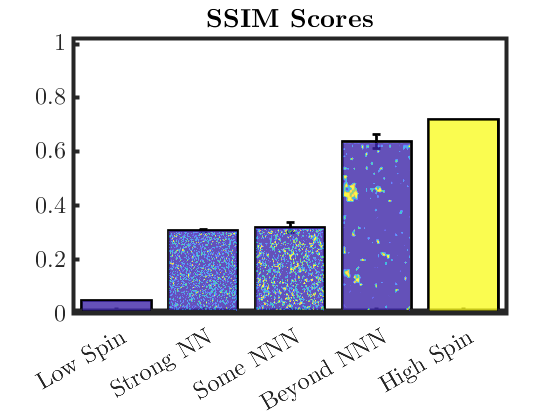

ssim_names = categorical({'Low Spin', 'High Spin', 'Strong NN', 'Some NNN', 'Beyond NNN'});
ssim_names = reordercats(ssim_names, {'Low Spin', 'Strong NN', 'Some NNN', 'Beyond NNN','High Spin'});
ssim_values = [0.0483, 0.7174, nn_ssim_avg, quad_ssim_avg, lin_ssim_avg];

figure;
bar(ssim_names, ssim_values, 'FaceColor', 'none', "LineWidth",2);
%ylim([0.984 1])
title('SSIM Scores')

hold on
ssim_std = [0, 0, nn_ssim_std, quad_ssim_std, lin_ssim_std];
errorbar(ssim_names(3), ssim_values(3), ssim_std(3), 'k', 'LineWidth', 2)
errorbar(ssim_names(4), ssim_values(4), ssim_std(4), 'k', 'LineWidth', 2)
errorbar(ssim_names(5), ssim_values(5), ssim_std(5), 'k', 'LineWidth', 2)
ax = gca;
ax.FontName = 'CMU Serif';
ax.FontSize = 18;
ax.YLim = ([0, 1]);
ax.YTick = ([0 0.2 0.4 0.6 0.8 1]);
ax.LineWidth = 3;
ax.Box = 'off';

ax2 = axes;
ax2.Box = 'on';
ax2.XTick = ([]);
ax2.YTick = ([]);
ax2.LineWidth = 3;
ax2.Color = 'none';
ax2.InnerPosition = ([0.1300 0.26 0.7750 0.65]);

ax3 = axes('Position',[0.146 0.26 0.1230 0.0232]);
patch([0 1 1 0],[0 0 1 1],[0.2422 0.1504 0.659], 'FaceAlpha', 0.8)
ax3.XTick = ([]);
ax3.YTick = ([]);
ax3.Box = 'off';
ax3.Color = 'none';

ax4 = axes('Position', [0.3 0.26 0.1230 0.190]);
imagesc(J48(1:800, 1:800), 'AlphaData',0.8)
ax4.XTick = ([]);
ax4.YTick = ([]);
ax4.Box = 'off';
ax4.Color = 'none';

ax5 = axes('Position', [0.455 0.26 0.1230 0.197]);
imagesc(J48_quad(1:800, 1:800), 'AlphaData',0.8)
ax5.XTick = ([]);
ax5.YTick = ([]);
ax5.Box = 'off';
ax5.Color = 'none';

ax6 = axes('Position', [0.61 0.26 0.1230 0.400]);
imagesc(J48_lin(1:1000, 1:500), 'AlphaData',0.8)
ax6.XTick = ([]);
ax6.YTick = ([]);
ax6.Box = 'off';
ax6.Color = 'none';

ax7 = axes('Position', [0.7652 0.26 0.1230 0.455]);
%imagesc(zerosImg(1:1000, 1:500), 'AlphaData',0.8, )
patch([0 1 1 0],[0 0 1 1],[0.9769 0.9839 0.0805], 'FaceAlpha', 0.75)
ax7.XTick = ([]);
ax7.YTick = ([]);
ax7.Box = 'off';
ax7.Color = 'none';

saveas(gcf, 'ssim_hist_LS_HS.png')

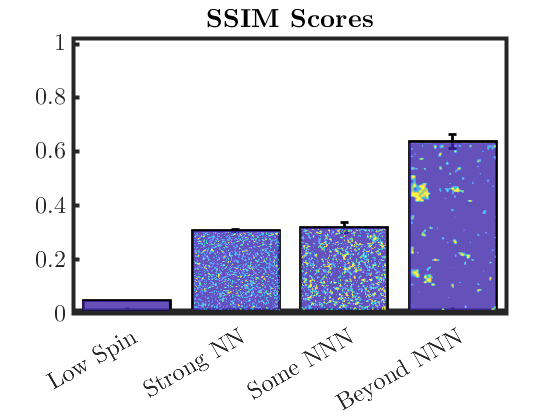

%% High spin removed
ssim_names = categorical({'Low Spin', 'Strong NN', 'Some NNN', 'Beyond NNN'});
ssim_names = reordercats(ssim_names, {'Low Spin', 'Strong NN', 'Some NNN', 'Beyond NNN'});
ssim_values = [0.0483, nn_ssim_avg, quad_ssim_avg, lin_ssim_avg];

figure;
bar(ssim_names, ssim_values, 'FaceColor', 'none', "LineWidth",2);
%ylim([0.984 1])
title('SSIM Scores')

hold on
ssim_std = [0, 0, nn_ssim_std, quad_ssim_std, lin_ssim_std];
errorbar(ssim_names(2), ssim_values(2), ssim_std(3), 'k', 'LineWidth', 2)
errorbar(ssim_names(3), ssim_values(3), ssim_std(4), 'k', 'LineWidth', 2)
errorbar(ssim_names(4), ssim_values(4), ssim_std(5), 'k', 'LineWidth', 2)
ax = gca;
ax.FontName = 'CMU Serif';
ax.FontSize = 18;
ax.YLim = ([0, 1]);
ax.YTick = ([0 0.2 0.4 0.6 0.8 1]);
ax.LineWidth = 3;
ax.Box = 'off';

ax2 = axes;
ax2.Box = 'on';
ax2.XTick = ([]);
ax2.YTick = ([]);
ax2.LineWidth = 3;
ax2.Color = 'none';
ax2.InnerPosition = ([0.1300 0.26 0.7750 0.65]);

ax3 = axes('Position',[0.146 0.26 0.155 0.0232]);
patch([0 1 1 0],[0 0 1 1],[0.2422 0.1504 0.659], 'FaceAlpha', 0.8)
ax3.XTick = ([]);
ax3.YTick = ([]);
ax3.Box = 'off';
ax3.Color = 'none';

ax4 = axes('Position', [0.345 0.26 0.155 0.190]);
imagesc(J48(1:800, 1:800), 'AlphaData',0.8)
ax4.XTick = ([]);
ax4.YTick = ([]);
ax4.Box = 'off';
ax4.Color = 'none';

ax5 = axes('Position', [0.535 0.26 0.1550 0.197]);
imagesc(J48_quad(1:800, 1:800), 'AlphaData',0.8)
ax5.XTick = ([]);
ax5.YTick = ([]);
ax5.Box = 'off';
ax5.Color = 'none';

ax6 = axes('Position', [0.73 0.26 0.1550 0.400]);
imagesc(J48_lin(1:1000, 1:500), 'AlphaData',0.8)
ax6.XTick = ([]);
ax6.YTick = ([]);
ax6.Box = 'off';
ax6.Color = 'none';

saveas(gcf, 'ssim_hist_LS.png')

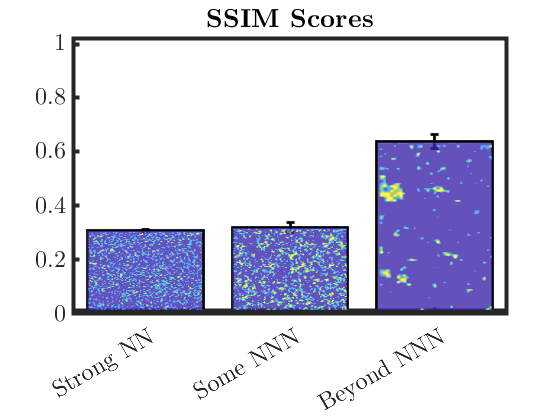

%% High spin removed
ssim_names = categorical({'Strong NN', 'Some NNN', 'Beyond NNN'});
ssim_names = reordercats(ssim_names, {'Strong NN', 'Some NNN', 'Beyond NNN'});
ssim_values = [nn_ssim_avg, quad_ssim_avg, lin_ssim_avg];

figure;
bar(ssim_names, ssim_values, 'FaceColor', 'none', "LineWidth",2);
%ylim([0.984 1])
title('SSIM Scores')

hold on
ssim_std = [0, 0, nn_ssim_std, quad_ssim_std, lin_ssim_std];
errorbar(ssim_names(1), ssim_values(1), ssim_std(3), 'k', 'LineWidth', 2)
errorbar(ssim_names(2), ssim_values(2), ssim_std(4), 'k', 'LineWidth', 2)
errorbar(ssim_names(3), ssim_values(3), ssim_std(5), 'k', 'LineWidth', 2)
ax = gca;
ax.FontName = 'CMU Serif';
ax.FontSize = 18;
ax.YLim = ([0, 1]);
ax.YTick = ([0 0.2 0.4 0.6 0.8 1]);
ax.LineWidth = 3;
ax.Box = 'off';

ax2 = axes;
ax2.Box = 'on';
ax2.XTick = ([]);
ax2.YTick = ([]);
ax2.LineWidth = 3;
ax2.Color = 'none';
ax2.InnerPosition = ([0.1300 0.26 0.7750 0.65]);

ax4 = axes('Position', [0.155 0.26 0.205 0.190]);
imagesc(J48(1:800, 1:800), 'AlphaData',0.8)
ax4.XTick = ([]);
ax4.YTick = ([]);
ax4.Box = 'off';
ax4.Color = 'none';

ax5 = axes('Position', [0.415 0.26 0.205 0.197]);
imagesc(J48_quad(1:800, 1:800), 'AlphaData',0.8)
ax5.XTick = ([]);
ax5.YTick = ([]);
ax5.Box = 'off';
ax5.Color = 'none';

ax6 = axes('Position', [0.674 0.26 0.205 0.400]);
imagesc(J48_lin(1:1000, 1:500), 'AlphaData',0.8)
ax6.XTick = ([]);
ax6.YTick = ([]);
ax6.Box = 'off';
ax6.Color = 'none';

saveas(gcf, 'ssim_hist.png')

## Random Comparison spin added

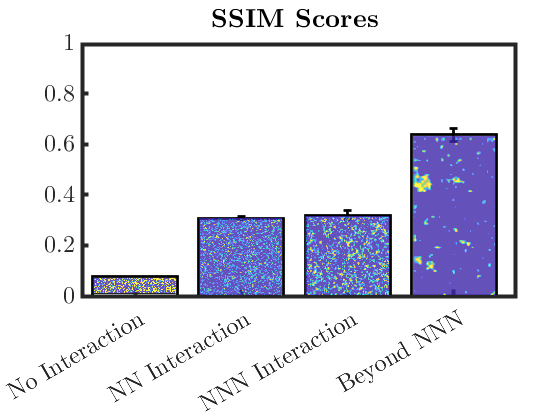


ssim_names = categorical({'No Interaction','NN Interaction', 'NNN Interaction', 'Beyond NNN'});
ssim_names = reordercats(ssim_names, {'No Interaction','NN Interaction', 'NNN Interaction', 'Beyond NNN'});
ssim_values = [rand_ssim, nn_ssim_avg, quad_ssim_avg, lin_ssim_avg];

figure;
bar(ssim_names, ssim_values, 'FaceColor', 'none', "LineWidth",2);
%ylim([0.984 1])
title('SSIM Scores')

hold on
ssim_std = [0, 0, nn_ssim_std, quad_ssim_std, lin_ssim_std];
errorbar(ssim_names(2), ssim_values(2), ssim_std(3), 'k', 'LineWidth', 2)
errorbar(ssim_names(3), ssim_values(3), ssim_std(4), 'k', 'LineWidth', 2)
errorbar(ssim_names(4), ssim_values(4), ssim_std(5), 'k', 'LineWidth', 2)
ax = gca;
ax.FontName = 'CMU Serif';
ax.FontSize = 18;
ax.YLim = ([0, 1]);
ax.YTick = ([0 0.2 0.4 0.6 0.8 1]);
ax.LineWidth = 3;
ax.Box = 'off';

ax2 = axes;
ax2.Box = 'on';
ax2.XTick = ([]);
ax2.YTick = ([]);
ax2.LineWidth = 3;
ax2.Color = 'none';
ax2.InnerPosition = ([0.146 0.295 0.7750 0.6]);

ax3 = axes('Position',[0.1655 0.30 0.149 0.038]);
%patch([0 1 1 0],[0 0 1 1],[0.2422 0.1504 0.659], 'FaceAlpha', 0.8)
imagesc(randImg(1:500, 1:500), 'AlphaData',0.8)
ax3.XTick = ([]);
ax3.YTick = ([]);
ax3.Box = 'off';
ax3.Color = 'none';

ax4 = axes('Position', [0.355 0.295 0.149 0.185]);
imagesc(J48(1:800, 1:800), 'AlphaData',0.8)
ax4.XTick = ([]);
ax4.YTick = ([]);
ax4.Box = 'off';
ax4.Color = 'none';

ax5 = axes('Position', [0.545 0.295 0.149 0.19]);
imagesc(J48_quad(1:800, 1:800), 'AlphaData',0.8)
ax5.XTick = ([]);
ax5.YTick = ([]);
ax5.Box = 'off';
ax5.Color = 'none';

ax6 = axes('Position', [0.735 0.295 0.149 0.38]);
imagesc(J48_lin(1:1000, 1:500), 'AlphaData',0.8)
ax6.XTick = ([]);
ax6.YTick = ([]);
ax6.Box = 'off';
ax6.Color = 'none';

saveas(gcf, 'ssim_hist_rand.png')